# `Digital Watermarking`

clc
close all
clear all

### `I. Introduction:`

`In a world where vast amounts of digital information are generated and transferred daily, safeguarding data integrity and protecting intellectual property rights poses significant challenges. Leading technology companies employ methods like Digital Watermarking to preserve content authenticity and prevent unauthorized copying. These invisible markers embedded within digital content ensure detectability of any attempts to alter or copy the information. For instance, in the film industry, companies like Digital Watermarking utilize these markers to protect their rights in films and digital content, making unauthorized alterations or copying identifiable. The robustness of Digital Watermarking refers to its ability to withstand various changes, transmissions, or attacks. For example, Google employs advanced algorithms for Video Watermarking to ensure resistance to environmental changes and interferences, maintaining the system's integrity against potential challenges. These efforts, based on mathematical principles and advanced image processing techniques, aim to keep digital watermarking effective amidst unintended alterations or attacks.`

### `II. Comprehensive Questions:`

`5. Research the general structure of watermarking and how to extract the hidden image and provide a brief explanation.`

`answer: ``Watermarking is a technique used to embed information, such as a logo or copyright notice, into digital content like images, audio, or video. There are two main types of watermarking: visible and invisible.`

`1. Visible Watermarking: In this approach, the watermark is clearly visible on the content, typically overlaid on top of the original image or video. It's used for branding or copyright protection, but it's easily removable.`

`2. Invisible Watermarking: This method embeds the information into the content in such a way that it's imperceptible to human senses but can be detected or extracted using specialized algorithms. This is more robust for copyright protection.`

`The general process of extracting hidden information from invisible watermarks involves the following steps:`

`1. Detection: The first step is to detect the presence of the watermark within the content. This typically involves analyzing the content and looking for patterns or alterations that indicate the presence of the watermark.`

`2. Localization: Once the watermark is detected, the next step is to localize its exact location within the content. This ensures that only the embedded information is extracted without altering the original content.`

`3. Extraction: After localization, the embedded information is extracted from the content. This can involve various techniques depending on the watermarking method used. For example, in frequency domain watermarking, the watermark may be embedded in specific frequency components of the content, which need to be extracted carefully.`

`4. Verification: Finally, the extracted information is verified to ensure its accuracy and integrity. This may involve comparing it with the original watermark or using cryptographic techniques to verify its authenticity.`

`Overall, watermarking provides a means to embed and extract information from digital content, serving various purposes such as copyright protection, authentication, and content identification.`

`6. Research about SVD-based Watermarking and explain its hiding and revealing algorithm by presenting the required relationships.`

`answer: ``Singular Value Decomposition (SVD) based watermarking is a method that utilizes the mathematical technique of SVD to embed and extract watermarks from digital content, such as images.`

`Hiding Algorithm:`

`1. Input Image and Watermark: Let `$A$` represent the original image matrix and `$W$` represent the watermark matrix.`

`2. Perform Singular Value Decomposition (SVD) on Image: Decompose the original image matrix `$A$` into three matrices using SVD:`$A=U\Sigma V^T$. `Here, `$U$` is the orthogonal matrix of left singular vectors, `$\Sigma$` is the diagonal matrix of singular values, and `$V^T$` is the orthogonal matrix of right singular vectors.`

`3. Embedding Watermark: Modify the singular values of the image matrix `$\Sigma$` to embed the watermark. This can be achieved by adding or subtracting a fraction of the watermark matrix `$W$` to/from the singular values.`


$$B+\alpha W=U_W B_W V_W^T$$


`4. Reconstruction: Reconstruct the modified image matrix `$A_W$`:`

   
$$A_W ={\textrm{UB}}_W V^H$$


`Revealing Algorithm:`

`1. Input Modified Image: Take the modified image `$A_W$` as input.`

`2. Perform SVD: Decompose the modified image matrix `$A_W$` into three matrices using SVD:`

   
$$A_W^* =U^* B_W^* V^{*^T }$$


`3. Extract Watermark: This difference represents the embedded watermark:`

  
$$\begin{array}{l}
C^* =U_W B_W^* V_W^T \\
W^* =\frac{1}{\alpha }\left(C^* -B\right)
\end{array}$$


`4. Optional Post-processing: Apply any necessary post-processing techniques to enhance the extracted watermark and improve its quality or visibility.`

`By following these steps, SVD-based watermarking can embed and extract watermarks from digital images while maintaining the integrity and quality of the original content.`

`7. Research how to Blur an image and the effect of kernel size on the output and explain how to create this filter on the image.`

`answer: ``Blurring an image is a common technique used in image processing to reduce noise, smooth out details, or blur specific regions. One popular method for blurring images is applying a Gaussian blur.`

`Gaussian Blur:`

- `Kernel Definition: A Gaussian kernel is a matrix of values that define the blurring effect. The values in the kernel are weighted according to a Gaussian distribution, with higher weights towards the center and lower weights towards the edges.`

- `Effect of Kernel Size: The size of the kernel determines the extent of blurring. A larger kernel size results in more significant blurring, as it considers a larger neighborhood of pixels when calculating the blurred value for each pixel. However, larger kernels also increase computation time.`

- `Creating the Filter: - Kernel Generation: To create a Gaussian blur filter, you first generate a 2D Gaussian function based on the desired standard deviation (sigma) and kernel size. - Normalization: Normalize the kernel to ensure that the sum of all its values equals 1. This ensures that the brightness of the image remains consistent after blurring. - Convolution: Apply the Gaussian kernel to the image using convolution. Convolution involves sliding the kernel over the image and calculating the weighted sum of pixel values within the kernel neighborhood for each pixel in the output image.`

`Effect of Kernel Size on Output:`

- `Smaller Kernel Size: Produces a subtle blur effect, preserving more details in the image.`

- `Larger Kernel Size: Results in a more pronounced blur effect, smoothing out finer details but potentially reducing sharpness and clarity.`

`In summary, to blur an image using a Gaussian blur filter, you generate a Gaussian kernel, normalize it, and convolve it with the original image. Adjusting the kernel size allows you to control the extent of blurring, with larger kernel sizes resulting in more pronounced blur effects.`

video = VideoReader('background.avi');
hidden_image = imread('3.jpg');
height = video.Height;
width = video.Width;
hidden_image_resized = imresize(hidden_image, [height, width]);

frame_index = 100;
frame = read(video, frame_index);
[rows, cols, ~] = size(frame);

[U, S, V] = svd(double(rgb2gray(frame)));

alpha = 0.01;
S_new = S + alpha * double(rgb2gray(hidden_image_resized));
[U_w, S_w, V_w] = svd(S_new);
frame_hidden = uint8(U * S_new * V.');

[U_1, S_w1, V_1] = svd(double(frame_hidden));
hidden_image_reconstructed = uint8(U_w * S_w1 * V_w');
hidden_image_extracted = 1/alpha*(double(hidden_image_reconstructed) - double(S));

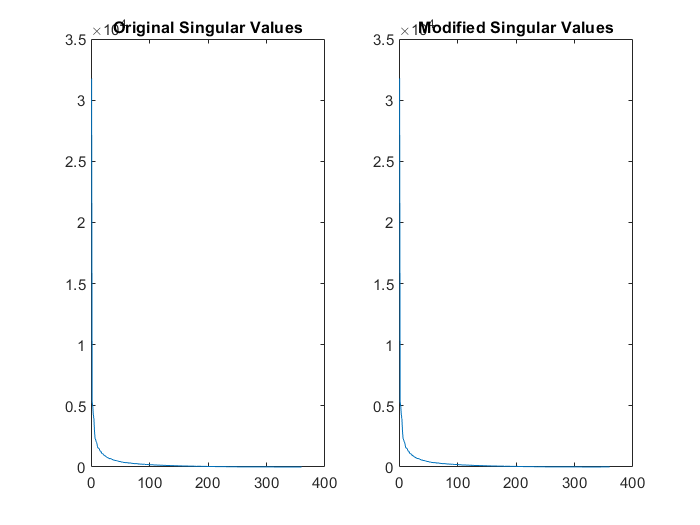

figure;
subplot(1,2,1);
plot(diag(S))
title('Original Singular Values');
subplot(1,2,2);
plot(diag(S_new))
title('Modified Singular Values');

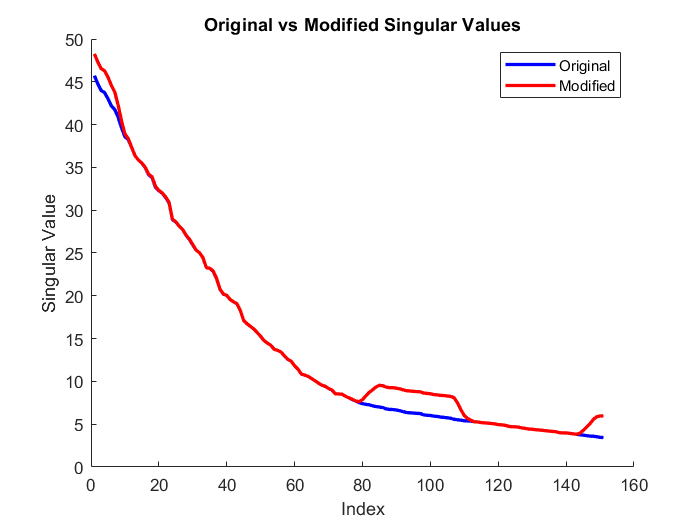

figure;
hold on;
plot(diag(S(200:350,200:350)), 'b', 'LineWidth', 2);
plot(diag(S_new(200:350,200:350)), 'r', 'LineWidth', 2);
hold off;
title('Original vs Modified Singular Values');
xlabel('Index');
ylabel('Singular Value');
legend('Original', 'Modified')

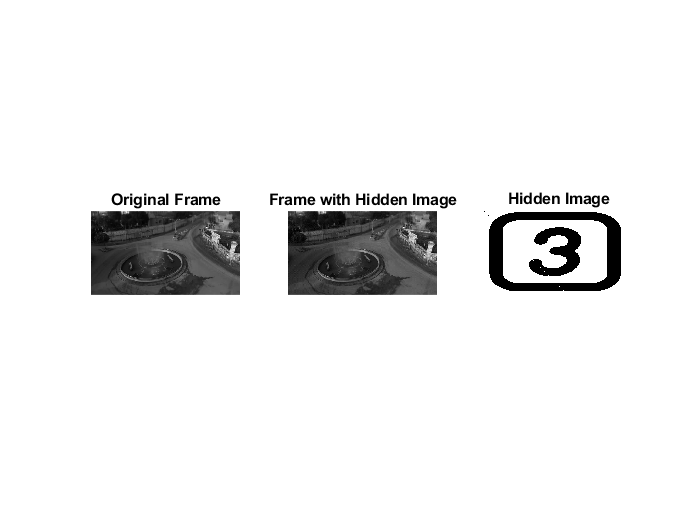

figure;
subplot(1,3,1);
imshow(frame);
title('Original Frame')
subplot(1,3,2);
imshow(frame_hidden)
title('Frame with Hidden Image');
subplot(1,3,3);
imshow(hidden_image_extracted)
title('Hidden Image');

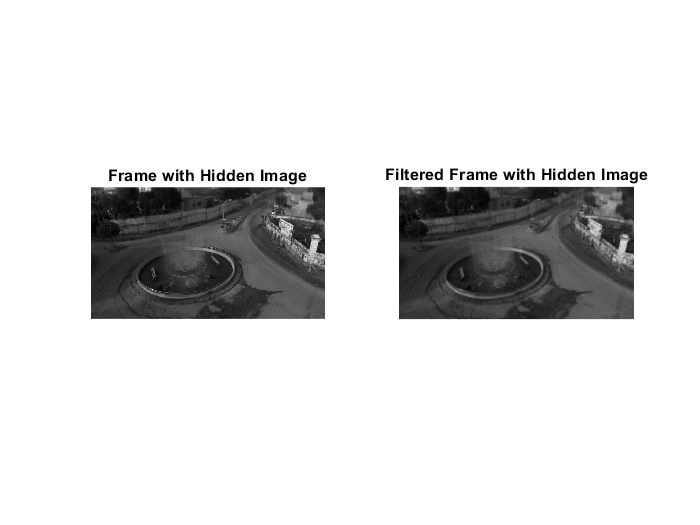

filter_size = 5;
sigma = 1.5;
filter_kernel = fspecial('gaussian', [filter_size filter_size], sigma);

frame_filtered = imfilter(frame_hidden, filter_kernel, 'replicate');

[U_filtered, S_filtered, V_filtered] = svd(double(im2gray(frame_filtered)));
S_new_filtered = S_filtered + alpha * double(rgb2gray(hidden_image_resized));
frame_hidden_filtered = uint8(U_filtered * S_new_filtered * V_filtered');

figure;
subplot(1,2,1);
imshow(frame_hidden);
title('Frame with Hidden Image')
subplot(1,2,2);
imshow(frame_hidden_filtered)

title('Filtered Frame with Hidden Image');